yb = 1;         % global y pos of body
xb = 0;         % global x pos of body
l1 = 0.3;       % lenght of the upper leg
l2 = 0.4;       % length of the lower leg
lb = 0.4;       % length of half the body
theta = 0;      % global angle of body
q1 = 120;       % shoulder joint angle
q2 = 90;        % elbow joint angle
h = 0.1;        % height of the body

% Forces
Fxb = -1;
Fyb = 9.81;
Fxf = 1;
Fyf = 9.81;

Fb = [Fxb, Fyb]

Fb =    -1.0000    9.8100


Ff = [Fxf, Fyf]

Ff =     1.0000    9.8100


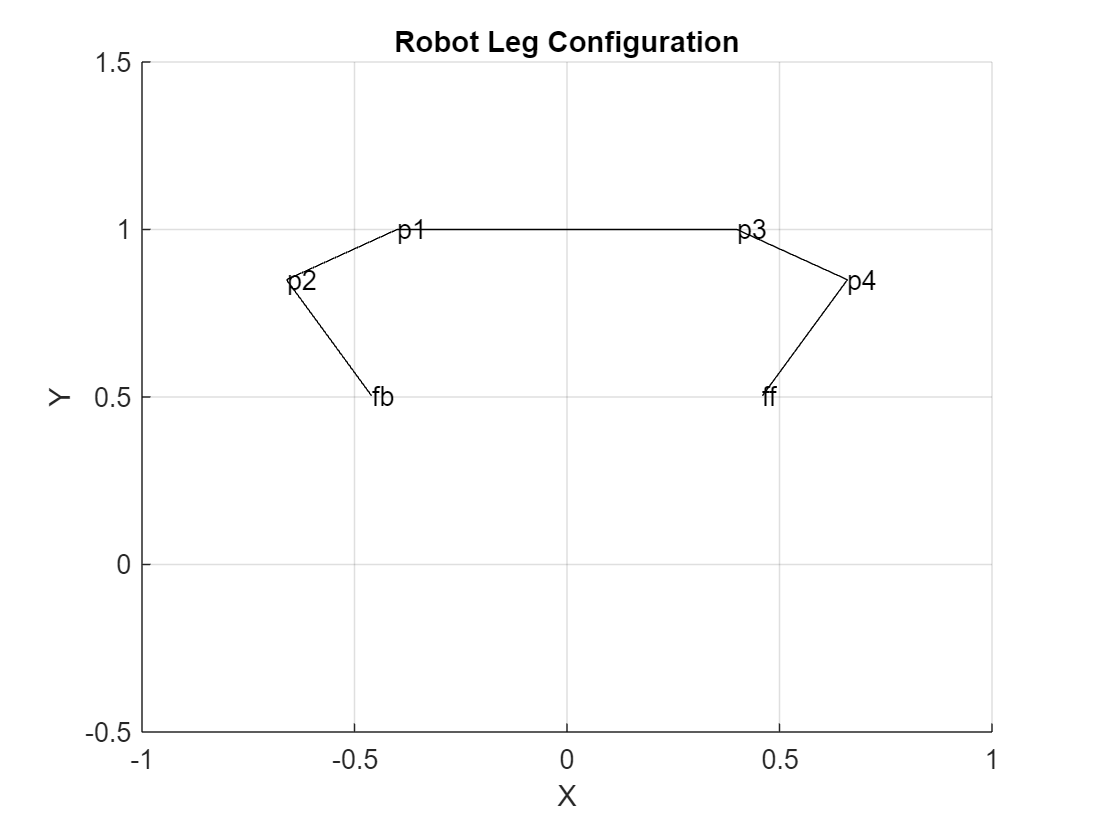


% Mass
M = 1;

% Inertia
J = (1/12)*M*h^2*(2*lb)^2;


pb = [xb,yb];

% Back Leg Points
p1 = [xb-lb*cosd(theta), yb - lb*sind(theta)];
p2 = [p1(1)-l1*sind(q1+theta), p1(2) + l1*cosd(q1+theta)];

% Front Leg Points
p3 = [xb+lb*cosd(theta), yb + lb*sind(theta)];
p4 = [p3(1) + l1*sind(q1-theta), p3(2) + l1*cosd(q1-theta)];

% Back Foot
fb = [p2(1) + l2*sind(q1-q2+theta), p2(2) - l2*cosd(q1-q2+theta)];

% Front Foot
ff = [p4(1) - l2*sind(q1-q2-theta), p4(2) - l2*cosd(q1-q2-theta)];



% Define the polygons using the points
hold on
back_leg = [p1; p2]; % Polygon for back leg
front_leg = [p3; p4]; % Polygon for front leg
back_foot = [p2; p4]; % Polygon for back foot

% Plot the polygons
hold on;
xlim([-1,1]);
ylim([-.5,1.5]);
fill(back_leg(:,1), back_leg(:,2), 'b'); % Plot back leg
%fill(front_leg(:,1), front_leg(:,2), 'r'); % Plot front leg
%fill(back_foot(:,1), back_foot(:,2), 'g'); % Plot back foot
plot([p1(1),p3(1)], [p1(2),p3(2)], 'k'); % Connect p1 to p3
plot([p2(1),fb(1)], [p2(2),fb(2)], 'k'); % Connect p2 to fb
plot([p3(1),p4(1)], [p3(2),p4(2)], 'k'); % Connect p3 to p4
plot([p4(1),ff(1)], [p4(2),ff(2)], 'k'); % Connect p4 to ff


% Add labels for each point
text(p1(1), p1(2), 'p1');
text(p2(1), p2(2), 'p2');
text(p3(1), p3(2), 'p3');
text(p4(1), p4(2), 'p4');
text(fb(1), fb(2), 'fb');
text(ff(1), ff(2), 'ff');

hold off;

% Add labels and grid
xlabel('X');
ylabel('Y');
title('Robot Leg Configuration');
grid on;

slopetop = (p3(2)-p1(2))/(p3(1)-p1(1))

slopetop = 0

slopelow = (p4(2)-p2(2))/(p4(1)-p2(1))

slopelow = 0


dist1 = pdist([p1;p2],"euclidean")

dist1 = 0.3000

dist2 = pdist([p3;p4], "euclidean")

dist2 = 0.3000


% Calculate distance from foot to body center
%rb = pdist([fb;pb],"euclidean")
%rf = pdist([ff;pb],"euclidean")
rb = [fb-pb,0]

rb =    -0.4598   -0.4964         0


rf = [ff-pb,0]

rf =     0.4598   -0.4964         0




tau_b = cross(rb, [Fb,0]);
tau_b = tau_b(3)

tau_b = -5.0071

tau_f = cross(rf, [Ff,0]);
tau_f = tau_f(3)

tau_f = 5.0071


bx_dotdot = (Fxb+Fxf)/M

bx_dotdot = 0

by_dotdot = (Fyb+Fyf)/M

by_dotdot = 19.6200

theta_dotdot = (tau_b + tau_f)/J

theta_dotdot = 0